Get Data H1 56-60 from api

dataPath = "C:\Users\bluep\Documents\MATLAB\hwML\dataset-3b.xlsx";
dataTable = readtable(dataPath, 'Sheet', 'Q1A');

% Specify the URL of the API
apiUrl = 'http://192.168.1.179/data';

% Use webread to fetch data from the API
jsonData = webread(apiUrl);

% Convert the JSON data to a MATLAB structure
jsonStruct = jsondecode(jsonencode(jsonData));

% Convert the structure array to a table
h1Table = struct2table(jsonStruct);

% Display the resulting table
disp('Table from JSON Data:');
disp(h1Table);

% dataTable.Height_S1(56:60) = futureOutputForecasted;
% writetable(dataTable,dataPath,"WriteMode","overwrite");

Predict Q1 56-60 from H1 56-60 (with mock up)

dataPath = "C:\Users\bluep\Documents\MATLAB\hwML\dataset-3b.xlsx";
dataTable_details = readtable(dataPath, 'Sheet', 'QH_S1');
mainDataTable = readtable(dataPath, 'Sheet','Q1A');

% Extract H_S1 and Q_S1 data
dataH1 = dataTable_details(:, "H_S1");
dataQ1 = dataTable_details(:, "Q_S1");

% Convert table data to arrays
H1 = table2array(dataH1);
Q1 = table2array(dataQ1);

norm_H1 = (H1 - mean(H1)) / std(H1);
norm_Q1 = (Q1 - mean(Q1)) / std(Q1);

% Fit a polynomial model
polyDegree = 3; % Change the degree as needed
polyModel = fit(norm_H1, norm_Q1, sprintf('poly%d', polyDegree));

% Test set (H1 values you want to predict Q1 for)
dataPreH = mainDataTable(56:60, "Height_S1");
testH1 = table2array(dataPreH);

norm_H1Pre = (testH1 - mean(H1)) / std(H1);

% Predict Q1 values for the test set
predicted_Q1 = feval(polyModel, norm_H1Pre);

predicted_Q1_denormalized = predicted_Q1 * std(Q1) + mean(Q1);

% Display or use the predicted values as needed
disp(predicted_Q1_denormalized);

   25.9345
   -6.8258
  233.9596
   59.3350
  177.2450



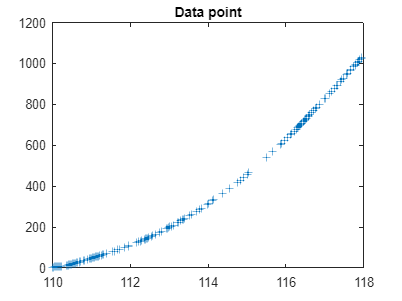


% Plot the data points
figure;
plot(H1, Q1, "Marker", "+", 'LineStyle', 'none', 'DisplayName', 'Data Points');
title('Data point');
hold on;

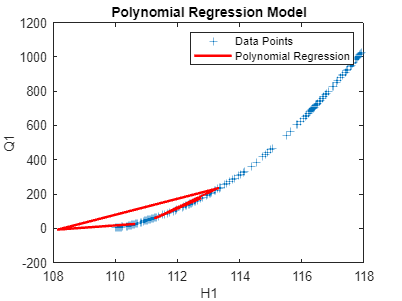


% Plot the data points and the regression curve
figure;
plot(H1, Q1, "Marker", "+", 'LineStyle', 'none', 'DisplayName', 'Data Points');
hold on;
plot(testH1, predicted_Q1_denormalized, 'r-', 'LineWidth', 2, 'DisplayName', 'Polynomial Regression');
hold off;

xlabel('H1');
ylabel('Q1');
legend('show');
title('Polynomial Regression Model');


mainDataTable.Discharge_S1(56:60) = predicted_Q1_denormalized;
writetable(mainDataTable, dataPath,"WriteMode","overwrite");

R-Square and MSE Prediction Q1 from H1

% Obtain the fitted values
fittedValues = feval(polyModel, norm_H1);

% Calculate R-squared for the fit
SSres = sum((norm_Q1 - fittedValues).^2);
SStotal = (length(norm_Q1) - 1) * var(norm_Q1);
R_squared = 1 - SSres / SStotal;

% Calculate Mean Squared Error (MSE)
MSE = sum((norm_Q1 - fittedValues).^2) / length(norm_Q1);

% Display the results
fprintf('R-squared: %.4f\n', R_squared);

R-squared: 0.9999


fprintf('Mean Squared Error (MSE): %.4f\n', MSE);

Mean Squared Error (MSE): 0.0001


F value 1-60

dataPath = "C:\Users\bluep\Documents\MATLAB\hwML\dataset-3b.xlsx";
dataTable = readtable(dataPath, "Sheet","Q1A");

% Generate random values for the new column
numRows = size(dataTable, 1);

% Perform the element-wise operation
fData = dataTable.Discharge_S3 - (dataTable.Discharge_S1 + dataTable.Discharge_S2);

% Add the new column to the table
dataTable.fValue = fData;

% Display the updated table
disp(dataTable);

    Day    Height_S1    Discharge_S1    Discharge_S2    Discharge_S3    fValue     Height_S3
    ___    _________    ____________    ____________    ____________    _______    _________

     1      117.87         1011.4            1630            3582         940.6     114.04  
     2      117.84         1004.8          1627.9            3519         886.3     113.89  
     3       117.8            996          1615.3            3442         830.7     113.73  
     4      117.74          983.1          1598.5            3365         783.4      113.6  
     5      117.66          965.9          1583.8          3297.5         747.8     113.49  
     6      117.65         963.75          1556.5          3206.5        686.25     113.37  
     7      117.5


writetable(dataTable,dataPath,"WriteMode","overwrite");

Plot Graph Relation F Value 1-60

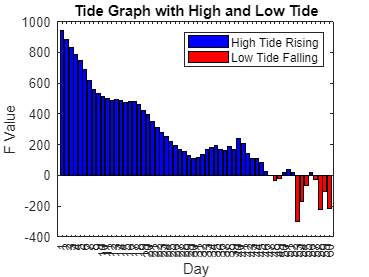

fData = fData(1:60);
positiveValues = fData(fData >= 0);
negativeValues = fData(fData < 0);

figure;
for i = 1:length(fData)
    if fData(i) >= 0
        bar(i, fData(i), 'b');
    else
        bar(i, fData(i), 'r');
    end
    hold on;
end
hold off;

xlim([0, length(fData) + 1]);
xticks(1:length(fData));

xlabel('Day');
ylabel('F Value');
title('Tide Graph with High and Low Tide');

% Create legend markers with desired colors
bluePatch = patch([0 1 1 0], [0 0 1 1], 'b');
redPatch = patch([0 1 1 0], [0 0 1 1], 'r');
legend([bluePatch, redPatch],'High Tide Rising', 'Low Tide Falling');

Calculate Q3 

dataPath = "C:\Users\bluep\Documents\MATLAB\hwML\dataset-3b.xlsx";
dataTable = readtable(dataPath, 'Sheet', 'Q1A');

% Extract input and output variables
Q1_cal = dataTable.Discharge_S1(1:60);
Q2_cal = dataTable.Discharge_S2(1:60);

Q3 = Q1_cal + Q2_cal

Q3 = 1.0e+03 *

    2.6414
    2.6327
    2.6113
    2.5816
    2.5497
    2.5202
    2.4843
    2.4507
    2.4276
    2.4045


disp(Q3)

   1.0e+03 *

    2.6414
    2.6327
    2.6113
    2.5816
    2.5497
    2.5202
    2.4843
    2.4507
    2.4276
    2.4045
    2.3814
    2.3541
    2.3247
    2.2959
    2.2796
    2.2636
    2.2536
    2.2457
    2.2419
    2.2361
    2.2343
    2.2345
    2.2367
    2.2327
    2.2205
    2.2062
    2.1919
    2.1772
    2.1545
    2.1298
    2.1050
    2.0784
    2.0442
    2.0194
    1.9815
    1.9438
    1.8970
    1.8295
    1.7757
    1.6623
    1.5999
    1.5733
    1.5120
    1.4367
    1.3240
    1.2412
    1.1543
    1.0767
    0.9720
    0.8956
    0.8404
    0.8064
    1.0473
    0.9781
    0.8902
    0.7602
    0.7396
    0.8862
    0.6759
    0.7221



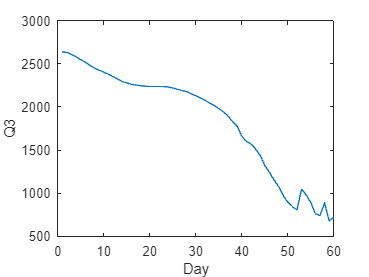


plot(Q3)
hold on;
xlabel('Day');
ylabel('Q3');
hold off

Predic H3 from Q3 1-60

% Load data
dataPath = "C:\Users\bluep\Documents\MATLAB\hwML\dataset-3b.xlsx";
dataTable_details = readtable(dataPath, 'Sheet', 'QH_S3');
mainDataTable = readtable(dataPath, 'Sheet','Q1A');

% Extract H_S3 and Q_S3 data
dataH3 = dataTable_details(:, "Q_S3");
dataQ3 = dataTable_details(:, "H_S3");

% Convert table data to arrays
H3 = table2array(dataH3);
Q3 = table2array(dataQ3);

norm_H3 = (H3 - mean(H3)) / std(H3);
norm_Q3 = (Q3 - mean(Q3)) / std(Q3);

% Fit a polynomial model
polyDegree = 5; % Change the degree as needed
polyModel = fit(norm_H3, norm_Q3, sprintf('poly%d', polyDegree));

% Test set (H3 values you want to predict Q3 for)
dataPreF = mainDataTable(:, "Discharge_S3");
PreH = table2array(dataPreF);

norm_PreH3 = (PreH - mean(H3)) / std(H3);

% Predict Q1 values for the test set
PreQ3 = feval(polyModel, norm_PreH3);

Denorm_PreQ3 = PreQ3 * std(Q3) + mean(Q3);

% Display or use the predicted values as needed
disp(Denorm_PreQ3);

  114.0413
  113.8902
  113.7322
  113.5974
  113.4939
  113.3697
  113.2427
  113.1289
  113.0720
  113.0216
  112.9777
  112.9253
  112.8947
  112.8557
  112.8158
  112.7996
  112.7832
  112.7500
  112.6902
  112.6372
  112.5733
  112.5071
  112.4585
  112.4086
  112.3368
  112.2627
  112.1864
  112.1418
  112.0391
  111.9569
  111.9212
  111.9092
  111.8971
  111.8730
  111.8242
  111.7002
  111.5861
  111.4961
  111.3397
  111.2475
  111.0354
  110.8364
  110.6326
  110.4599
  110.1770
  109.8875
  109.6785
  109.4803
  109.3157
  109.2452
  109.1889
  109.0898
  108.9460
  109.0542
  109.0827
  109.0040
  108.8796
  108.7955
  108.6136
  108.4613
       NaN
       NaN
       NaN
       NaN
       NaN



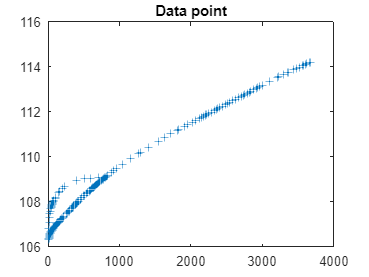


% add to table
mainDataTable.Height_S3 = Denorm_PreQ3;
writetable(mainDataTable,dataPath,"WriteMode","overwrite");
% Plot the data points
figure;
plot(H3, Q3, "Marker", "+", 'LineStyle', 'none', 'DisplayName', 'Data Points');
title('Data point');
hold on;

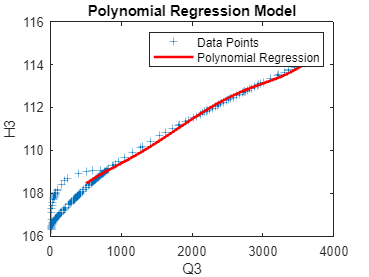


% Plot the data points and the regression curve
figure;
plot(H3, Q3, "Marker", "+", 'LineStyle', 'none', 'DisplayName', 'Data Points');
hold on;
plot(PreH, Denorm_PreQ3, 'r-', 'LineWidth', 2, 'DisplayName', 'Polynomial Regression');
hold off;

xlabel('Q3');
ylabel('H3');
legend('show');
title('Polynomial Regression Model');

R-Square and MSE Prediction H3 from Q3

% Obtain the fitted values
fittedValues = feval(polyModel, norm_H3);

% Calculate R-squared for the fit
SSres = sum((norm_Q3 - fittedValues).^2);
SStotal = (length(norm_Q3) - 1) * var(norm_Q3);
R_squared = 1 - SSres / SStotal;

% Calculate Mean Squared Error (MSE)
MSE = sum((norm_Q3 - fittedValues).^2) / length(norm_Q3);

% Display the results
fprintf('R-squared: %.4f\n', R_squared);

R-squared: 0.9618


fprintf('Mean Squared Error (MSE): %.4f\n', MSE);

Mean Squared Error (MSE): 0.0381


Post H3 1-60 to api

% Example table data
data = table('Size', [3, 2], 'VariableNames', {'Name', 'Value'});
data.Name = {'Parameter1', 'Parameter2', 'Parameter3'};
data.Value = [10, 20, 30];

% Specify the URL of the API
apiUrl = 'https://api.example.com/post_endpoint';

% Convert the table data to a structure (JSON format)
jsonData = table2struct(data);

% Use webwrite to make a POST request with table data
response = webwrite(apiUrl, jsonData, 'RequestMethod', 'post', 'ContentType', 'json');

% Display or process the response
disp(response);

Forecast H1 61-65

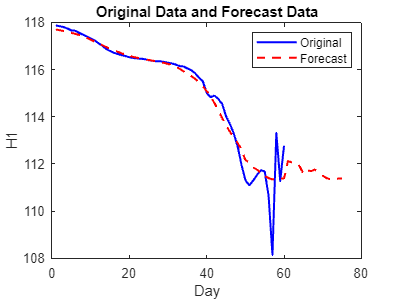

% Read data from Excel file
dataPath = "C:\Users\bluep\Documents\MATLAB\hwML\dataset-3b.xlsx";
dataTable = readtable(dataPath, 'Sheet', 'Q1A');

% Extract input and output variables
input = dataTable.Discharge_S1(1:60);
output = dataTable.Height_S1(1:60);

% Choose forecasting method (Moving Average in this example)
windowSize = 5; % Adjust the window size as needed

% Data Visualization
% hold on
% plot(1:length(output), output, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Original Data');
% xlabel('N');
% ylabel('Output (fValue)');
% title('Original Data and Forecasted Values');
% hold off

% Forecasting Method (Moving Average)
outputForecasted = movmean(output, windowSize);

% Forecast Future Data
futureInput = dataTable.Discharge_S3(61:end);
futureOutputForecasted = movmean(output(end - windowSize + 1:end), windowSize);

forecastedValues = [outputForecasted; futureOutputForecasted];
% Plot the forecasted values
figure;
plot(1:length(output), output, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Forecasted Values');
hold on
plot(1:length(output)+5, forecastedValues, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Forecasted Values');
title("Original Data and Forecast Data");
xlabel("Day");
ylabel("H1");
legend("Original","Forecast");
hold off


% Display the forecasted values for the next 5 data points
disp('Forecasted Values for the Next 5 Data Points:');

Forecasted Values for the Next 5 Data Points:


disp(futureOutputForecasted);

  112.1125
  112.0700
  112.0310
  111.9045
  111.5917
  111.7238
  111.6921
  111.7640
  111.6264
  111.4985
  111.3950
  111.3436
  111.3470
  111.3756
  111.3862




% Function to calculate R-squared
mean_actual = mean(output);
numerator = sum((output - outputForecasted).^2);
denominator = sum((output - mean_actual).^2);
r_squared = 1 - (numerator / denominator);

% Function to calculate Mean Squared Error (MSE)
% function mse = calculate_mse(actual, predicted)
n = length(output);
mse = sum((output - outputForecasted).^2) / n;

% Display R-squared and MSE
disp(['R-squared: ', num2str(r_squared)]);

R-squared: 0.93381


disp(['MSE: ', num2str(mse)]);

MSE: 0.34324




dataTable.Height_S1(61:65) = futureOutputForecasted;

Error using  . 
Unable to perform assignment because the left and right sides have a different number of elements.

writetable(dataTable,dataPath,"WriteMode","overwrite");

Predict Q1 61-65 from forecast H1 61-65

% Load data
dataPath = "C:\Users\bluep\Documents\MATLAB\hwML\dataset-3b.xlsx";
dataTable_details = readtable(dataPath, 'Sheet', 'QH_S1');
mainDataTable = readtable(dataPath, 'Sheet','Q1A');

% Extract H_S1 and Q_S1 data
dataH1 = dataTable_details(:, "H_S1");
dataQ1 = dataTable_details(:, "Q_S1");

% Convert table data to arrays
H1 = table2array(dataH1);
Q1 = table2array(dataQ1);

norm_H1 = (H1 - mean(H1)) / std(H1);
norm_Q1 = (Q1 - mean(Q1)) / std(Q1);

% Fit a polynomial model
polyDegree = 5; % Change the degree as needed
polyModel = fit(norm_H1, norm_Q1, sprintf('poly%d', polyDegree));

% Test set (H1 values you want to predict Q1 for)
dataPreH1 = mainDataTable(61:65, "Height_S1");
PreH1 = table2array(dataPreH1);
disp("PreH1");

PreH1


disp(PreH1);

  110.7000
  110.8450
  111.2300
  111.3775
  112.4533



norm_H1Pre = (PreH1 - mean(H1)) / std(H1);

% Predict Q1 values for the test set
predicted_Q1 = feval(polyModel, norm_H1Pre);

predicted_Q1_denormalized2 = predicted_Q1 * std(Q1) + mean(Q1);

% Display or use the predicted values as needed
disp(predicted_Q1_denormalized2);

   28.9862
   36.1992
   57.8757
   67.0932
  148.6128



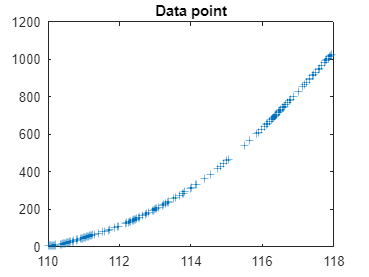


% Plot the data points
figure;
plot(H1, Q1, "Marker", "+", 'LineStyle', 'none', 'DisplayName', 'Data Points');
title('Data point');

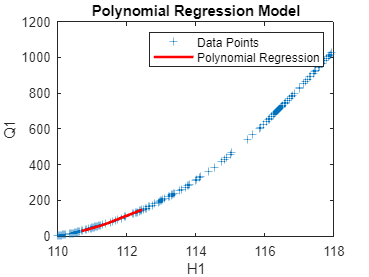


% Plot the data points and the regression curve
figure;
plot(H1, Q1, "Marker", "+", 'LineStyle', 'none', 'DisplayName', 'Data Points');
hold on;
plot(PreH1, predicted_Q1_denormalized2, 'r-', 'LineWidth', 2, 'DisplayName', 'Polynomial Regression');
hold off;
xlabel('H1');
ylabel('Q1');
legend('show');
title('Polynomial Regression Model');


mainDataTable.Discharge_S1(61:65) = predicted_Q1_denormalized2;
writetable(mainDataTable,dataPath,"WriteMode","overwrite");

R-Square and MSE Prediction Q1 from H1

% Obtain the fitted values
fittedValues = feval(polyModel, norm_H1);

% Calculate R-squared for the fit
SSres = sum((norm_Q1 - fittedValues).^2);
SStotal = (length(norm_Q1) - 1) * var(norm_Q1);
R_squared = 1 - SSres / SStotal;

% Calculate Mean Squared Error (MSE)
MSE = sum((norm_Q1 - fittedValues).^2) / length(norm_Q1);

% Display the results
fprintf('R-squared: %.4f\n', R_squared);

R-squared: 1.0000


fprintf('Mean Squared Error (MSE): %.4f\n', MSE);

Mean Squared Error (MSE): 0.0000
